full_lnp = importdata('C:\Users\ngraf\Documents\GitHub\blebbed_lnp_simulations\lnp_meshes\full_lnp.mat');
empty_lnp =importdata('C:\Users\ngraf\Documents\GitHub\blebbed_lnp_simulations\lnp_meshes\empty_lnp.mat');
blebbed_lnp = importdata('C:\Users\ngraf\Documents\GitHub\blebbed_lnp_simulations\lnp_meshes\blebbed_lnp.mat');

%% ========================================================================
%  Solve BEM for LNP populations against a real glass/water substrate,
%  following the documented +optics workflow (Hitzelhammer et al.,
%  "Unified Simulation Platform for Interference Microscopy", ACS
%  Photonics SI, demoiscat01.m pattern).
%  ========================================================================

%% ---- wavelength (match your laser / filter) ----
lambda = 555;              % nm
k0 = 2 * pi / lambda;

%% ---- substrate: glass coverslip below, aqueous buffer above (z=0 interface) ----
% NOTE: this water index must match whatever the LNP meshes were built
% against (n_medium = 1.335 in lnp_populations_nanobem.m) -- the layer's
% upper medium and the particle's "outside" material need to agree
% physically even though they're separate Material objects here.
n_glass = 1.515;           % check against your actual coverslip glass
n_water = 1.335;
mat_glass = Material(n_glass^2, 1);
mat_water = Material(n_water^2, 1);
layer = stratified.layerstructure([mat_glass, mat_water], 0);

%% ---- illumination: match your actual microscope geometry ----
% pol = polarization, dir = propagation direction. dir=[0,0,1] illuminates
% from below (through the glass, upward into the water/particle side),
% the standard inverted-microscope epi-iSCAT geometry. For oblique/
% off-axis illumination, tilt dir; for a transmissive COBRI setup,
% illumination instead comes from the water side (dir=[0,0,-1]) with the
% detection lens on the glass side.
pol = [1, 0, 0];
dir = [0, 0, 1];
einc = optics.decompose(k0, pol, dir);

%% -------------------------------------------------------------------------
%  1. Solve single-boundary populations (empty_lnp and full_lnp)
% -------------------------------------------------------------------------
single_pops = {'empty_lnp', 'full_lnp'};

for p = 1:numel(single_pops)
    pop_name = single_pops{p};
    pop_data = eval(pop_name);
    fprintf('Solving BEM for %s...\n', pop_name);
    for i = 1:numel(pop_data)
        tau  = pop_data{i}.tau;
        qinc = einc(tau, 'layer', layer);              % inhomogeneities incl. secondary fields
        bem  = stratified.bemsolver(tau, layer, 'order', []);
        pop_data{i}.sol = bem \ qinc;
    end
    assignin('caller', pop_name, pop_data);
end

Solving BEM for empty_lnp...
Solving BEM for full_lnp...


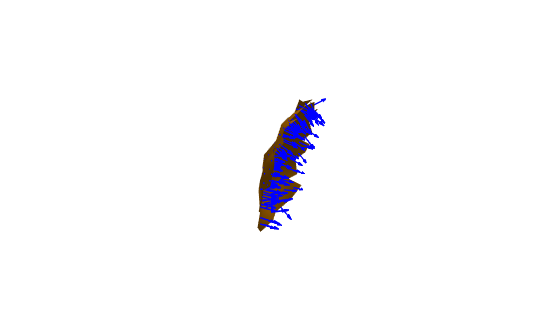

figure; plot(blebbed_lnp{1}.tau_interface, 'nvec', true);


% -------------------------------------------------------------------------
%  2. Solve multi-boundary population (blebbed_lnp)
% -------------------------------------------------------------------------
fprintf('Solving BEM for blebbed_lnp...\n');

Solving BEM for blebbed_lnp...


for i = 1:numel(blebbed_lnp)
    % All THREE boundaries -- exterior lipid, exterior aqueous, AND the
    % internal lipid/aqueous interface -- are required to close the
    % multi-region system.
    tau = [blebbed_lnp{i}.tau_lipid_out, ...
       blebbed_lnp{i}.tau_aqueous_out, ...
       blebbed_lnp{i}.tau_interface];

    qinc = einc(tau, 'layer', layer);
    bem = stratified.bemsolver(tau, layer, 'order', 5);

    blebbed_lnp{i}.tau = tau;
    blebbed_lnp{i}.sol = bem \ qinc;
end

DEBUG rad1=[1 383] rad2=[1 383]
DEBUG rad1=[1 383] rad2=[1 551]
DEBUG rad1=[1 551] rad2=[1 383]
DEBUG rad1=[1 551] rad2=[1 551]
DEBUG rad1=[1 195] rad2=[1 195]
DEBUG rad1=[1 195] rad2=[1 297]
DEBUG rad1=[1 297] rad2=[1 195]
DEBUG rad1=[1 297] rad2=[1 297]
DEBUG rad1=[1 190] rad2=[1 190]
DEBUG rad1=[1 190] rad2=[1 272]
DEBUG rad1=[1 272] rad2=[1 190]
DEBUG rad1=[1 272] rad2=[1 272]
DEBUG rad1=[1 403] rad2=[1 403]
DEBUG rad1=[1 403] rad2=[1 291]
DEBUG rad1=[1 291] rad2=[1 403]
DEBUG rad1=[1 291] rad2=[1 291]
DEBUG rad1=[1 325] rad2=[1 325]
DEBUG rad1=[1 325] rad2=[1 197]
DEBUG rad1=[1 197] rad2=[1 325]
DEBUG rad1=[1 197] rad2=[1 197]
DEBUG rad1=[1 111] rad2=[1 111]
DEBUG rad1=[1 111] rad2=[1 255]
DEBUG rad1=[1 255] rad2=[1 111]
DEBUG rad1=[1 255] rad2=[1 255]
DEBUG rad1=[1 248] rad2=[1 248]
DEBUG rad1=[1 248] rad2=[1 188]
DEBUG rad1=[1 188] rad2=[1 248]
DEBUG rad1=[1 188] rad2=[1 188]
DEBUG rad1=[1 178] rad2=[1 178]
DEBUG rad1=[1 178] rad2=[1 140]
DEBUG rad1=[1 140] rad2=[1 178]
DEBUG ra

%% ========================================================================
%  Propagate solved BEM fields to simulated camera images, following the
%  documented +optics imaging pipeline (SI Sec. "A simple example").
%  Run this after solve_lnp_populations.m.
%  ========================================================================

%% ---- microscope parameters: TUNE THESE TO MATCH YOUR ACTUAL SETUP ----
NA = 1.45;                  % objective numerical aperture
oil = Material(1.45, 1);      % image-side medium (after tube lens)

% Optical axis rotation: default lensimage axis is +z. Illumination here
% comes from below (dir=[0,0,1] in solve_lnp_populations.m) and detection
% happens through the SAME objective below the sample (epi-iSCAT), so we
% rotate the lens's collection direction to -z, exactly as in the SI
% example. For a transmissive COBRI setup (detection on the opposite
% side from illumination), you likely do NOT want this rotation --
% check against demoiscat01.m and your specific geometry.
rot = optics.roty(180);

% mat_glass here must be the SAME material used for the layer's lower
% medium in solve_lnp_populations.m -- it's what the objective looks
% through.
lens = optics.lensimage(mat_glass, oil, k0, NA, 'rot', rot);

% Reference field: reflection of the incoming excitation at the
% substrate interface, propagating back down toward the objective --
% this IS the iSCAT reference wave, computed directly from the physical
% substrate reflection rather than added by hand.
refl = secondary(einc, layer, 'dir', 'down');

% Image grid and focus -- TUNE to match your camera's field of view and
% pixel size, and your experimental focus/defocus offset.
x = 2000 * linspace(-1, 1, 201);   % nm, image-plane coordinates
z_focus = 500;                      % nm, focus plane position (defocus offset)
focus = [0, 0, z_focus];

%% ---- helper: compute one iSCAT image from a solved boundary+solution ----
function [im, contrast] = render_iscat_image(sol, lens, refl, x, focus)
    far  = farfields(sol, lens.dir);
    isca = efield(lens, far,  x, x, 'focus', focus);
    iref = efield(lens, refl, x, x, 'focus', focus);
    isca = flip(isca, 1);   % flip x-axis, consequence of the rot=180 lens axis
    iref = flip(iref, 1);

    im  = dot(isca + iref, isca + iref, 3);   % total interference intensity
    ibg = dot(iref, iref, 3);                  % reference-only (background) intensity
    contrast = (im - ibg) ./ ibg * 100;        % iSCAT contrast, percent
end

%% ---- render images for each population ----
pops = {'empty_lnp', 'full_lnp', 'blebbed_lnp'};

for p = 1:numel(pops)
    pop_name = pops{p};
    pop_data = eval(pop_name);
    fprintf('Rendering iSCAT images for %s...\n', pop_name);
    for i = 1:numel(pop_data)
        [im, contrast] = render_iscat_image(pop_data{i}.sol, lens, refl, x, focus);
        pop_data{i}.image    = im;
        pop_data{i}.contrast = contrast;
    end
    assignin('caller', pop_name, pop_data);
end

Rendering iSCAT images for empty_lnp...


Unrecognized field name "sol".


%% ---- quick look ----
figure;
subplot(1,3,1); imagesc(x, x, empty_lnp{1}.contrast);   axis image; colorbar; title('empty LNP');
subplot(1,3,2); imagesc(x, x, full_lnp{1}.contrast);    axis image; colorbar; title('full LNP');
subplot(1,3,3); imagesc(x, x, blebbed_lnp{1}.contrast); axis image; colorbar; title('blebbed LNP');
colormap(gca, 'gray');